# Design Cooling System

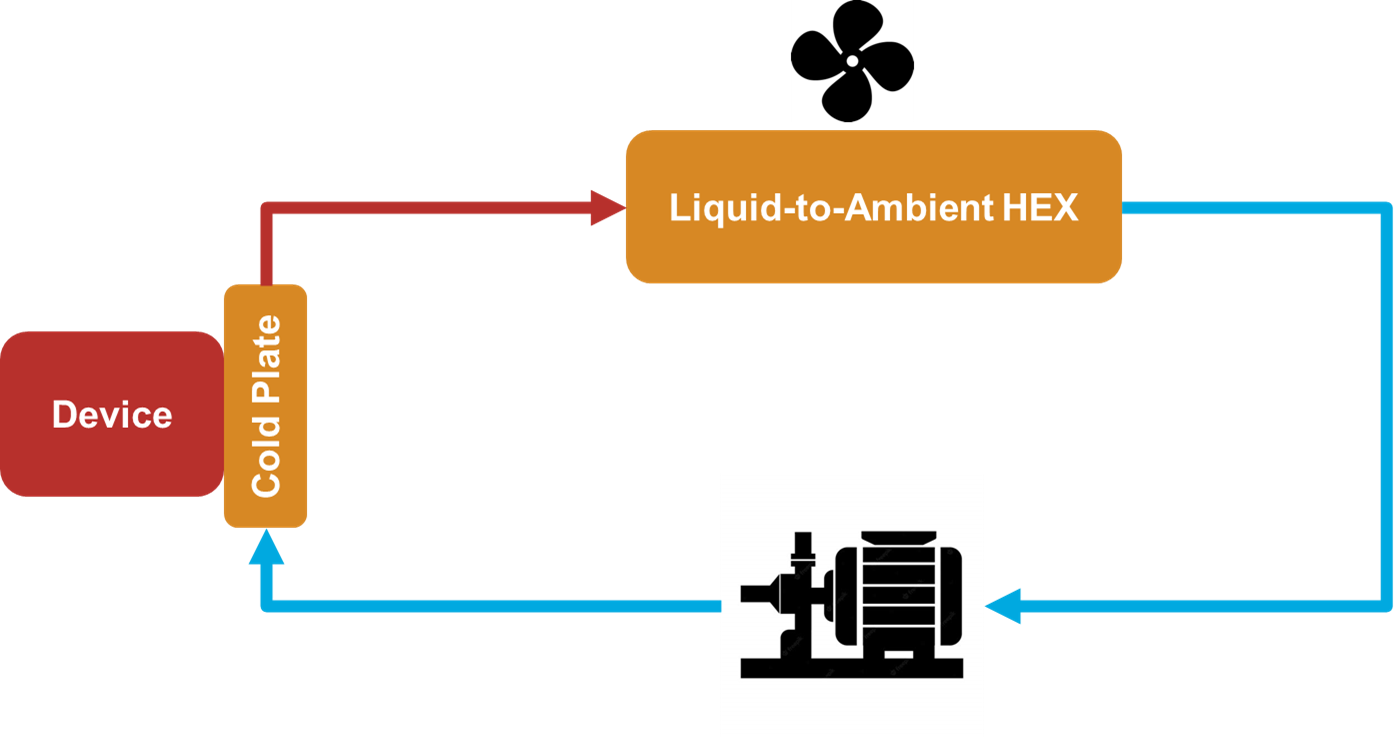

### Requirements for X-Ray Tube Cooling

- Remove up to 2 kW 

- Allowed coolant temperature rise 5°C

- Temperature set point: 25°C

- Device temperature should not exceed 50°C

- Working fluid: Water

- Temperature stability +/- n°C

- Operating conditions: (at what temperatures is the thing operated and “where” is it) 15°C-40°C

- Tout must ot excess 30°C 

Steady state calculations

Final surface temperature of cooled device


$$T_{\textrm{surface}} =Q_{\textrm{Diss}} *R_{\textrm{CP}} \;+T_{\textrm{cp},\textrm{out}}$$


Cold plate heat transfer


$$Q_{\textrm{Diss}} =\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{cp},\textrm{in}} \right)*{\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$


Heat transfer in ambient air heat exchanger


$$Q_{\textrm{Diss}} =\varepsilon *C_{\min } *\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{Air}} \right)$$


with 


$$C_{\textrm{water}} =\;$$

$${\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$



$$C_{\textrm{air}} =\;$$

$${\dot{m} }_{\textrm{air}} *c_{p,\textrm{air}}$$



$$C_{\min } =\min \left(C_{\textrm{water}} ,C_{\textrm{air}} \right)$$


#### Requirements and operating conditions

QDot            = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantIn      = 25;           % (°C) Assumed coolant inlet temperature
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature
TSurfaceMax     = 50;           % (°C) Maximum device temperature
TAmbient        = 20;           % (°C) Ambient temperature

#### Water properties at 25°C 

cpCoolant       = 4181;         % (J/(kg*K)) heat cpacity
rhoCoolant      = 997;          % (kg/m^3) density
muCoolant       = 0.00105;      % Pa·s
kCoolant        = 0.6;          % W/(m*K)
PrCoolant       = 6.13          % (1) Prandtl number

PrCoolant = 6.1300

#### Air porperties at 20°C

cpAir           = 1006;         % (J/(kg*K)) heat cpacity
rhoAir          = 1.204;        % (kg/m^3) density
kinViscAir      = 15e-6;        % (m^2/s) kinematic viscosity
PrAir           = 0.71;         % (1) Prandtly number
kAir            = 0.026;        % W/(m*K) 

#### Cold Plate

#### Determine required flow rate at operating conditions

mDot    = QDot/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;        % (l/min) Volumetric flow rate

Test steady state cold plate outlet temperature for different flow rates at constant heat

VDotLPMVec = 2:8;                                      % l/min
mDotVec    = VDotLPMVec*0.001/60*rhoCoolant;            % kg/s
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

plot(VDotLPMVec,TCoolantOutVec)
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
hold on

Verify in Simscape model 

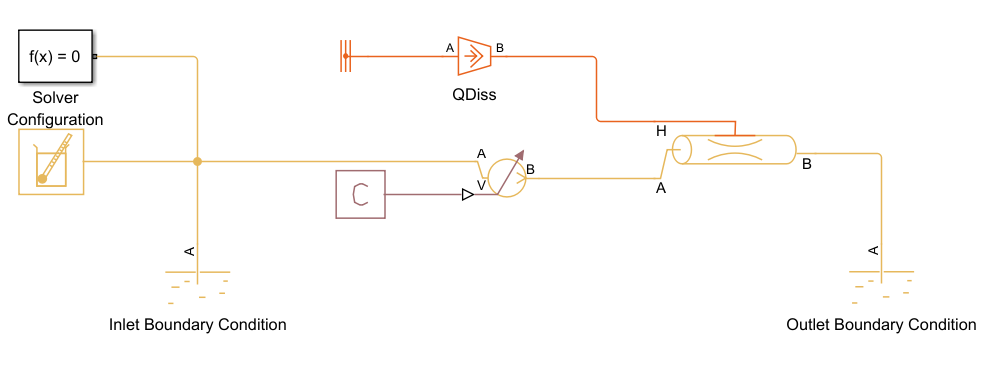

Notes:

- Talk about "boundary conditions" (also downstrean vs upstream)

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_TCoolantOut_SteadyState');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[08-Aug-2025 14:00:56] Running simulations...
[08-Aug-2025 14:01:05] Completed 1 of 7 simulation runs
[08-Aug-2025 14:01:05] Completed 2 of 7 simulation runs
[08-Aug-2025 14:01:06] Completed 3 of 7 simulation runs
[08-Aug-2025 14:01:06] Completed 4 of 7 simulation runs
[08-Aug-2025 14:01:06] Completed 5 of 7 simulation runs
[08-Aug-2025 14:01:06] Completed 6 of 7 simulation runs
[08-Aug-2025 14:01:06] Completed 7 of 7 simulation runs


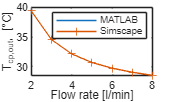


TCoolantOutVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutVecSim(i) = TCoolantOutTemp(end);
end
clear TCoolantOutTemp simInp

plot(VDotLPMVec,TCoolantOutVecSim,'-+')
xlabel('Flow rate [l/min]')
ylabel('T_{cp,out}, [°C]');
legend('MATLAB','Simscape')
hold off

#### Cold plate resistance for maximum surface temperature at maximum coolant outlet temperature

Rcp = (TSurfaceMax - TCoolantOutMax)/QDot;   % K/W

Test resistance for different flow rates/outlet temperature 

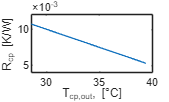

VDotLPMVec      = 2:8;     % (lpm)
mDotVec         = VDotLPMVec*0.001/60*rhoCoolant;    
TCoolantOutVec  = QDot./(mDotVec*cpCoolant)+TCoolantIn;

RcpVec = (TSurfaceMax - TCoolantOutVec)/QDot;   % K/W

figure
plot(TCoolantOutVec,RcpVec)
xlabel('T_{cp,out}, [°C]');
ylabel('R_{cp} [K/W]')

Verify in Simscape model

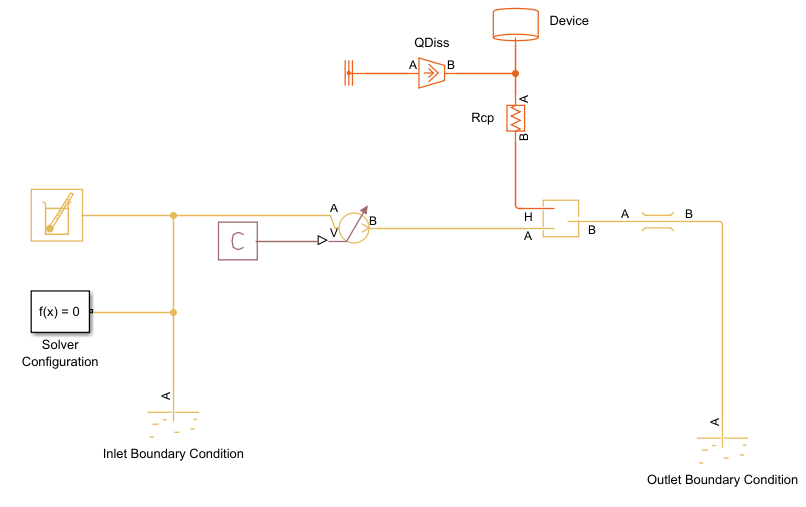

Notes:

- Talk about Chamber vs. Pipe

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_Rcp_Chamber_SteadyState');
    simInp(i) = simInp(i).setVariable('Rcp',RcpVec(i));
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp);

[08-Aug-2025 14:01:08] Running simulations...
[08-Aug-2025 14:01:10] Completed 1 of 7 simulation runs
[08-Aug-2025 14:01:11] Completed 2 of 7 simulation runs
[08-Aug-2025 14:01:12] Completed 3 of 7 simulation runs
[08-Aug-2025 14:01:13] Completed 4 of 7 simulation runs
[08-Aug-2025 14:01:14] Completed 5 of 7 simulation runs
[08-Aug-2025 14:01:14] Completed 6 of 7 simulation runs
[08-Aug-2025 14:01:15] Completed 7 of 7 simulation runs


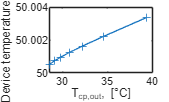


TDeviceOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
end
clear TDeviceTemp  simInp
figure
plot(TCoolantOutVec,TDeviceOutSim,'-+')
xlabel('T_{cp,out}, [°C]');
ylabel('Device temperature [°C]')

**Size cold plate**

% Rcp goal = 0.01
% Example: Detector Cold Plate Spec Summary
% Material: Aluminum 167 W/m/K
% Size: 80 × 200 × 6 mm  
% Channels: Serpentine, 3.5 mm wide × 3 mm deep
% Channel length
% Wall thickness between channels >1mm
% Material thickness under channel floor >2mm

% Cold plate external dimensions
% Length 200-400 mm
% Width 100-300 mm
% Thickness 10-25 mm
% Surface area cold plate to X-Ray Tube
% Tube Diameter 50-120 mm
% Channel geometry
% Channel width 1-5 mm
% Channel depth 2-5 mm
% Channel pitch 2-10 mm
% Wall thickness 1-2 mmm
% Serpentine channels, channel length: 

cpL     = 250; % mm
cpW     = 150; % mm
deviceD = 75; % mm
cpDeviceSurfaceArea = pi*(deviceD/1000/2)^2; % m^2
cpK         = 167; % W/(mÜK)
cpThickness = 7; % mm

channelWidth    = 5; % mm
channelHeight   = 4;   % mm
channelPitch    = 10; % mm
effFlowLength   = 220; % mm
numPasses       = 15; % number of channel passes 
numChannels     = 1;
channelLength   = numPasses*effFlowLength/1000*numChannels; % m 
channelArea     = channelHeight*channelWidth; % mm^2
channelDh       = channelWidth*channelHeight/(channelHeight+channelWidth); % mm
channelRoughness = 15e-6; % m


Test Rcp for given cold plate for different flow rates in Simscape model 

VDotLPMVec = 2:8;                    % l/min

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_ColdPlate_SteadyState');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp);

[08-Aug-2025 14:01:18] Running simulations...
[08-Aug-2025 14:01:20] Completed 1 of 7 simulation runs
[08-Aug-2025 14:01:21] Completed 2 of 7 simulation runs
[08-Aug-2025 14:01:22] Completed 3 of 7 simulation runs
[08-Aug-2025 14:01:22] Completed 4 of 7 simulation runs
[08-Aug-2025 14:01:23] Completed 5 of 7 simulation runs
[08-Aug-2025 14:01:24] Completed 6 of 7 simulation runs
[08-Aug-2025 14:01:25] Completed 7 of 7 simulation runs


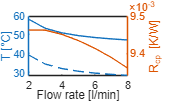


TDeviceOutSim  = zeros(size(VDotLPMVec));
TCoolantOutSim = zeros(size(VDotLPMVec));

for i = 1:numel(VDotLPMVec)
    TDeviceTemp = simOut(i).simlog.Device.M.T.series.values('degC');
    TDeviceOutSim(i) = TDeviceTemp(end);
    TCoolantOutTemp = simOut(i).simlog.Pipe_TL.B.T.series.values('degC');
    TCoolantOutSim(i) = TCoolantOutTemp(end);    
end

clear TDeviceTemp  TCoolantOutTemp simInp

RcpSim = (TDeviceOutSim-TCoolantOutSim)/QDot;

figure
yyaxis left
plot(VDotLPMVec,TDeviceOutSim,VDotLPMVec,TCoolantOutSim);
ylabel('T [°C]')

yyaxis right
plot(VDotLPMVec, RcpSim);
ylabel('R_{cp} [K/W]')

xlabel('Flow rate [l/min]')
hold off

#### Determine pressure drop

% Reynolds number
velPipe         = VDot/(channelArea*1e-6);           % (m/s) Flow velocity
Re              = rhoCoolant*velPipe*(channelDh/1000)/muCoolant; % Reynolds number

% Darcy friction factor 
if Re < 2300
    f = 64 / Re;     % Laminar flow
else
    
    f = 1 / (-1.8 * log10(6.9/Re + (channelRoughness/(channelDh/1000)/3.7)^1.11))^2; % Turbulent flow - Haaland correlation
end
% Pressure drop (not accounting for temperature differences)
deltaPCP = f * (channelLength/(channelDh/1000)) * 0.5 * rhoCoolant * velPipe^2; % (Pa)

Test pressure drop for different flow rates 

VDotLPMVec = 2:8;                    % l/min
velPipeVec = VDotLPMVec*0.001/60/(channelArea*1e-6);   % (m/s) Flow velocity
ReVec      = rhoCoolant*velPipeVec*(channelDh/1000)/muCoolant;     % Reynolds number

fVec = zeros(size(VDotLPMVec));

% Darcy friction factor 
fVec(ReVec<2000) = 64./ReVec(ReVec<2000);
fVec(ReVec>=2000) = 1 ./ ...
    (-1.8 * log10(6.9./ReVec(ReVec>=2000) + (channelRoughness/(channelDh/1000)/3.7)^1.11)).^2; 

% Pressure drop
deltaPPipeVec = fVec*(channelLength/(channelDh/1000))*0.5*rhoCoolant.*velPipeVec.^2; % (Pa)

figure
plot(VDotLPMVec,deltaPPipeVec/1e6)
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
hold on

Test in Simscape model 

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_deltaP_SteadyState');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

[08-Aug-2025 14:01:27] Running simulations...
[08-Aug-2025 14:01:29] Completed 1 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 2 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 3 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 4 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 5 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 6 of 7 simulation runs
[08-Aug-2025 14:01:30] Completed 7 of 7 simulation runs


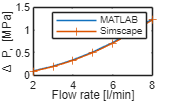


deltaPPipeVecSim = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    pATemp = simOut(i).simlog.Pipe_TL.A.p.series.values('Pa');
    pBTemp = simOut(i).simlog.Pipe_TL.B.p.series.values('Pa');
    deltaPPipeVecSim(i) = pATemp(end)-pBTemp(end);
end
clear pATemp pBTemp simInp

plot(VDotLPMVec,deltaPPipeVecSim/1e6,'-+')
xlabel('Flow rate [l/min]')
ylabel('\Delta P, [MPa]');
legend('MATLAB','Simscape')
hold off

#### Radiator

TAirOut    = 24;    % (°C) Assumed air outlet temperature

VDotAir    = 0.2; % (m^3/s) Assumed air flow rate
mDotAir    = VDotAir*rhoAir; % kg/s 
hAir       = 100; % W/(m^2*K) Assumed heat transfer coefficient air side

% % LMTD
% deltaT1 = TCoolantOutMax - TAirOut;
% deltaT2 = TCoolantIn - TAmbient;
% 
% if deltaT1 == deltaT2
%     deltaTLM = deltaT1;
% else
%     deltaTLM = (deltaT1 - deltaT2) / log(deltaT1 / deltaT2);
% end
% % Required heat transfer area with assumed parameters
% ARequired = QDot / deltaTLM/hAir; % (m^2)


#### **Size the Radiator**

% Single pass cross flow HEX
% Air enters at ambient temperatre
% Fan creates air flow of 0.2 m^3/s 
% Coolant inlet temperature (max) : 30°C
% Coolant inlet temperature (desired): 25°C
% Coolant flow rate (nominal): VDotLPM

HEXCoreL = 350; % mm
HEXCoreH = 350; % mm
HEXCoreW = 88;  % mm
HEXTubeW = 88; % mm
HEXTubeH = 2; %mm
HEXTubeL = 350; % mm

HEXTubeWOuter = HEXTubeW+1; % mm
HEXTubeHOuter = HEXTubeH+1; % mm

numTubes = 15;

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter*0)*HEXTubeL; % mm^2
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL; % mm^2
DhTubes = 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH);

tubeRoughness = 15e-6;  % m

finEfficiency = 0.75;
finSpacing = 2; % mm
gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1); % mm
areaAirFlow = (numTubes - 1)*HEXCoreH*gapHTubes; % mm^2
numFins = (numTubes-1)*HEXCoreL/finSpacing;
areaAirFins = 2*numFins*HEXCoreW*gapHTubes; % mm^2


areaAirTotal = (areaAirFins*finEfficiency+areaOuterTubes)/1e6;

Test in Simscape model for different thermal liquid flow rates

for i = numel(VDotLPMVec):-1:1
    simInp(i) = Simulink.SimulationInput('example_Radiator_SteadyState');
    simInp(i) = simInp(i).setVariable('VDotLPM',VDotLPMVec(i));
end

simOut = sim(simInp, UseFastRestart="on");

TCoolantOutVec = zeros(size(simInp));
TAirOutVec     = zeros(size(simInp));

for i = 1:numel(VDotLPMVec)
    TCoolantOutTemp = simOut(i).simlog.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
    TAirOutVecTemp  = simOut(i).simlog.Heat_Exchanger_TL_MA.B2.T.series.values('degC');
    TCoolantOutVec(i) = TCoolantOutTemp(end);
    TAirOutVec(i) = TAirOutVecTemp(end);
end
clear TCoolantOutTemp pBTemp simInp

plot(VDotLPMVec,[TCoolantOutVec',TAirOutVec'])
xlabel('Flow rate [l/min]')
ylabel('T [°C]');
legend('T_{Coolant,Out}','T_{Air,Out}')
hold off

Notes:

Next steps:

- Pressure drop radiotor

- Size Pump

- Test harnesses for dynamic model

- Assemble everything in a loop

- For hotter conditions: evaporator